**Top Level Summary:**

To solve the following using Rung Kutta Order 4 (RK4):


$$\left(\mathrm{Equation}\;1\right)\left\lbrace \begin{array}{c}
{h^{\prime } }^{\prime } \left(x\right)+\frac{2}{x}h^{\prime } \left(x\right)+h\left(x\right)=0,\\
h\left(0\right)=1,\\
h^{\prime } \left(0\right)=0
\end{array}\right.$$


Note we have in Matrix Form:


$$\left\lbrack \begin{array}{c}
f^{\prime } \\
h^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{2}{x} & -1\\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\\
h
\end{array}\right\rbrack$$



$$M_{i,j} =\left\lbrack \begin{array}{cc}
-\frac{2}{x} & -1\\
1 & 0
\end{array}\right\rbrack$$


We implement RK4, using the first order equations for $f^{\prime } ,h^{\prime }$ as determined in Q3 Part (b) 

4th Order (RK4) is used with $n=100\;\textrm{in}\;x\in \left\lbrack 0,\textrm{pi}\right\rbrack$. Then we plot $h\left(x\right)$

**Working and Implementation Summary:**

Interval of $x\in \left\lbrack 0,\textrm{pi}\right\rbrack$ has square brackets implying both 0 and pi **are** included. 

Observe a singularity for $M_{1,1} =-\frac{2}{x}$  when $x=0$

To resolve this, recall from that $f^{\prime } \left(0\right)$ = ${h^{\prime } }^{\prime } \left(0\right)=-1/3$

The Rung Kutta implementation has the following "quirks":

- The function is adapted using Matlab's "@" rather than writing each function repeatedly which incurs implementation time. After implementing and reflecting on the use of the @ approach to evaluating the equations, flexibility to be copied and pasted into other implementations was increased. Ability to parametrise in the programming sense in future where formulae may be passed through was also enhanced. 

- An "IF statement" is included to handle the point of singularity and then LH Eq 1 is used when x = 0. The positioning of the IF statement is not optimal (after testing the timing) but has been put here for easier readability. The "IF" for x = 0 should be done outside the loop and not re-evaluated for each iteration. As n = 100 moving it outside the loop would be cosmetics and non tangible but would be tangible for more complex systems and larger n and ranges of x. 

- A "cosmetics" function was created to allow various values of upper and lower bounds of the x-axis and n. A true/false toggle was included to produce a plot or not.

This function is called as follows:  Q3c($\left.x_0 ,x_n ,n\right)$ where $x_0 =0,\;\;x_n =\pi ,\;\;n=100$


$$h\left(0\right)=1,\;h\left(\pi \right)=-3\ldotp {139}^{-9}$$


x =      0

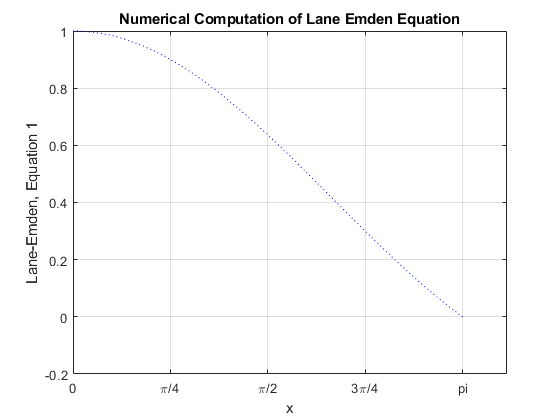

RKSolver(0,pi,100, true);